# Sesión 3: Ecuaciones no lineales

## Método de bisección

### Teorema de Bolzano:


$$f ~\mbox{continua en } [a,b] \wedge f(a)f(b)<0 \to ~\mbox{existe } a<\hat{x}<b, f(\hat{x})=0$$


- Continuidad se analiza formalmente (a mano)

- Cambio de signo

Problema:

$-x^2 + 2x + e^x=0$ con $[-1, 0]$

f=@(x) -x^2 + 2*x + exp(x)

f = function_handle with value:
    @(x)-x^2+2*x+exp(x)


a=-1; b=0;
if f(a)*f(b) < 0
    fprintf('f admite una raíz en [%.2f, %.2f]',a,b)
end

f admite una raíz en [-1.00, 0.00]

f(a)*f(b)

ans = -2.6321

Otro caso

h=@(x) sin(x)/x^2

h = function_handle with value:
    @(x)sin(x)/x^2



a=-1; b=0.0001;
h(a)

ans = -0.8415

h(b)

ans = 1.0000e+04

% asumimos que h es continua
if h(a)*h(b) < 0
    fprintf('f admite una raíz en [%.5f, %.5f]',a,b)
else
    disp('no se determina si hay raíz')
end

f admite una raíz en [-1.00000, 0.00010]

Graficando la función h

a=-1; b=1;
fplot(h,[a,b])

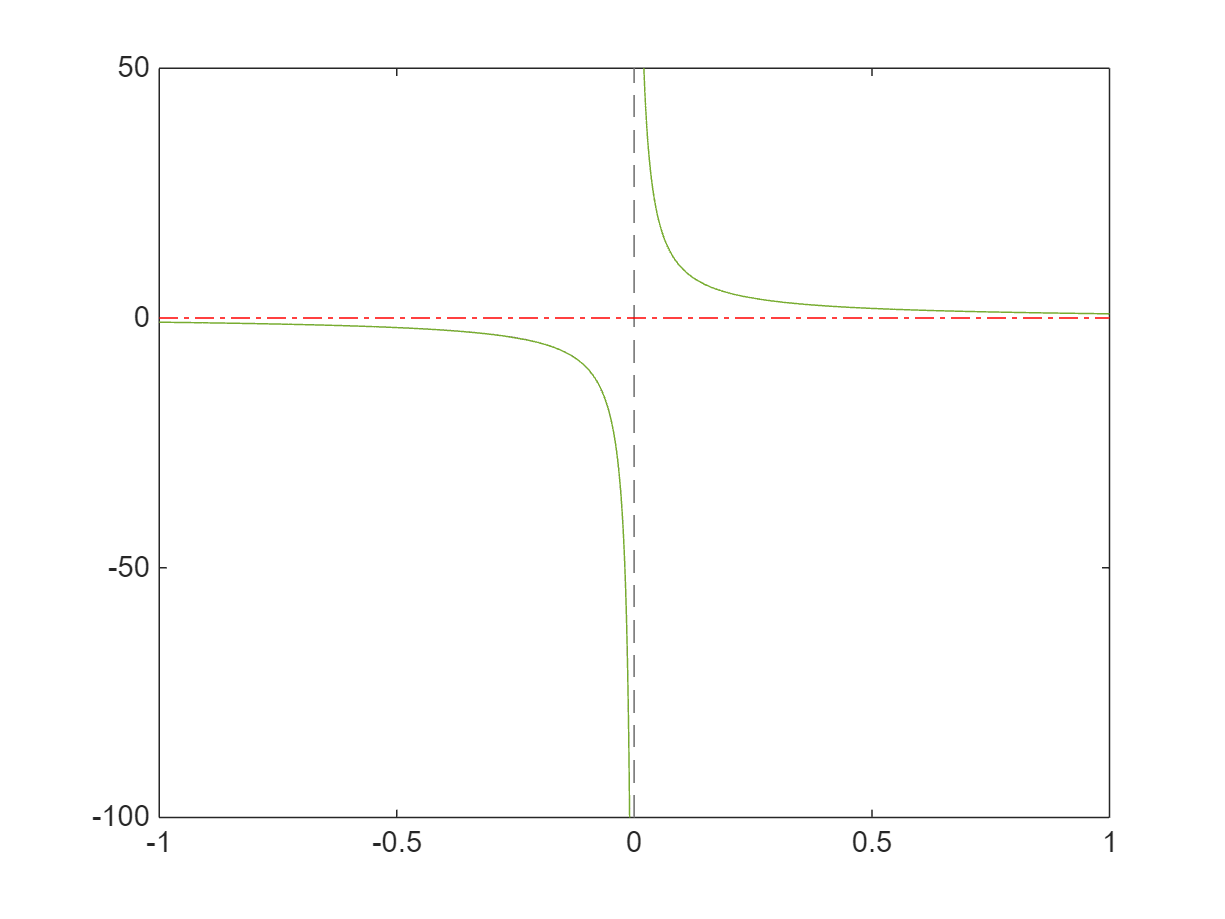

hold on;
yline(0,'r-.')

$h$ no es continua -> en este caso vemos que no hay raíces

### Método de bisección: versión 1

clear
format short

f=@(x) -x^2 + 2*x + exp(x);
a=-1; b=0;
Maxiter=10; % nro de iteraciones

z=biseccion(f,a,b,Maxiter);
disp(z)

         0   -1.0000   -0.5000         0   -2.6321   -0.6435    1.0000       NaN
    1.0000   -0.5000   -0.2500         0   -0.6435    0.2163    1.0000    0.2500
    2.0000   -0.5000   -0.3750   -0.2500   -0.6435   -0.2033    0.2163    0.1250
    3.0000   -0.3750   -0.3125   -0.2500   -0.2033    0.0090    0.2163    0.0625
    4.0000   -0.3750   -0.3438   -0.3125   -0.2033   -0.0966    0.0090    0.0312
    5.0000   -0.3438   -0.3281   -0.3125   -0.0966   -0.0436    0.0090    0.0156
    6.0000   -0.3281   -0.3203   -0.3125   -0.0436   -0.0173    0.0090    0.0078
    7.0000   -0.3203   -0.3164   -0.3125   -0.0173   -0.0042    0.0090    0.0039
    8.0000   -0.3164   -0.3145   -0.3125   -0.0042    0.0024    0.0090    0.0020
    9.0000   -0.3164   -0.3154   -0.3145   -0.0042   -0.0009    0.0024    0.0010
   10.0000   -0.3154   -0.3149   -0.3145   -0.0009    0.0008    0.0024    0.0005



x_root=z(end,3) % aproximación de la raíz luego de Maxiter iteraciones

x_root = -0.3149

disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),z(:,6),z(:,7),z(:,8),...
    'VariableNames',{'k','a','c','b','f(a)','f(c)','f(b)','error'}))

    k        a           c           b           f(a)          f(c)         f(b)         error   
    __    ________    ________    ________    __________    __________    _________    __________

     0          -1        -0.5           0       -2.6321      -0.64347            1           NaN
     1        -0.5       -0.25           0      -0.64347        0.2163            1          0.25
     2        -0.5      -0.375       -0.25      -0.64347      -0.20334       0.2163         0.125
     3      -0.375     -0.3125       -0.25      -0.20334     0.0089594       0.2163        0.0625
     4      -0.375    -0.34375     -0.3125      -0.20334     -0.096558    0.0089594       0.03125
     5    -0.34375    -0.32812     -0.312

### Ejercicio

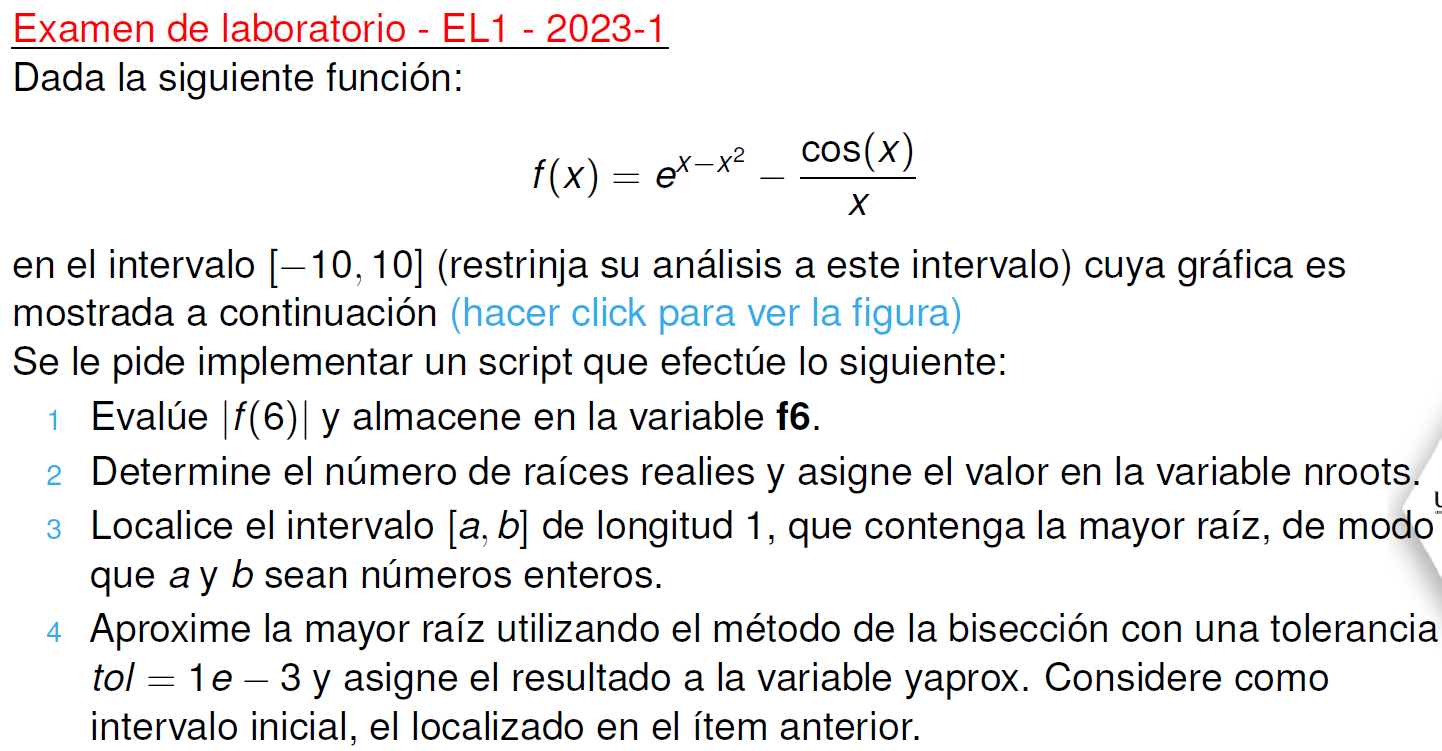

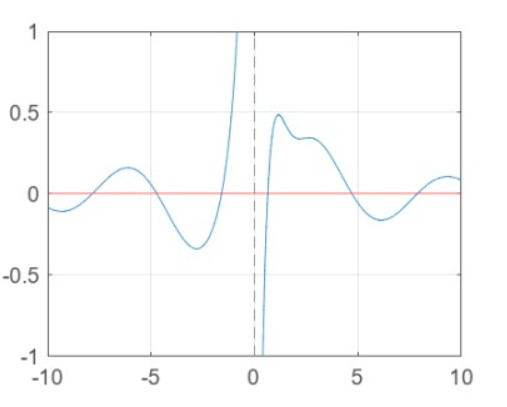

clear

f=@(x) exp(x-x^2)-cos(x)/x; 
% 1
f6 = abs(f(6))

f6 = 0.1600

% 2
nroots = 6; % 6 intersecciones con el eje X
% 3
a=7; b=8;
if f(a)*f(b) < 0
    fprintf('f admite una raíz en [%.2f, %.2f]',a,b)
end

f admite una raíz en [7.00, 8.00]

% 4
Tol=1e-3;
z=biseccion2(f,a,b,Tol);

Se necesita 9 iteraciones


%format long % formato de 8 decimales
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),z(:,6),z(:,7),z(:,8),...
    'VariableNames',{'k','a','c','b','f(a)','f(c)','f(b)','error'}))

    k      a         c         b          f(a)           f(c)          f(b)          error   
    _    ______    ______    ______    ___________    __________    ___________    __________

    0         7       7.5         8        -0.1077     -0.046218       0.018188           0.5
    1       7.5         8      7.75      -0.046218      0.018188      -0.013393          0.25
    2      7.75         8     7.875      -0.013393      0.018188      0.0026688         0.125
    3      7.75     7.875    7.8125      -0.013393     0.0026688     -0.0053081        0.0625
    4    7.8125     7.875    7.8438     -0.0053081     0.0026688     -0.0013044       0.03125
    5    7.8438     7.875    7.8594     -0.0013044     0.0026688     

### Método de bisección: versión 2

clear
format short

f=@(x) -x^2 + 2*x + exp(x);
a=-1; b=0;
Tol = 5e-5; % Tolerancia
z=biseccion2(f,a,b,Tol);

Se necesita 14 iteraciones


x_root=z(end,3) % aproximación de la raíz

x_root = -0.3151

N_iter=size(z,1)-1 % número de iteraciones

N_iter = 14

format long
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),z(:,6),z(:,7),z(:,8),...
    'VariableNames',{'k','a','c','b','f(a)','f(c)','f(b)','error'}))

    k            a                   c                    b                     f(a)                     f(c)                    f(b)                  error      
    __    _______________    _________________    __________________    _____________________    ____________________    _____________________    ________________

     0                 -1                 -0.5                     0        -2.63212055882856      -0.643469340287367                        1                 0.5
     1               -0.5                    0                 -0.25       -0.643469340287367                       1        0.216300783071405                0.25
     2               -0.5                -0.25                -0.375       

## Método de Newton

### Introducción al algoritmo

clear 
format short

f=@(x) exp(x-x^2)-cos(x)/x

f = function_handle with value:
    @(x)exp(x-x^2)-cos(x)/x


syms t
f(t)

$$ans = {\mathrm{e}}^{t-t^{2}}-\frac{\cos\left(t\right)}{t}$$

df_sym=diff(f(t),t)

$$df\_sym = \frac{\cos\left(t\right)}{t^{2}}+\frac{\sin\left(t\right)}{t}-{\mathrm{e}}^{t-t^{2}}\,\left(2\,t-1\right)$$

df=matlabFunction(df_sym)

df = function_handle with value:
    @(t)1.0./t.^2.*cos(t)+sin(t)./t-exp(t-t.^2).*(t.*2.0-1.0)


x0=1

x0 = 1

df(x0)

ans = 0.3818


$$x_{k+1}=x_k-\frac{f(x_x)}{f'(x_k)}$$


x1=x0-f(x0)/df(x0)

x1 = -0.2041

### Implementación del algoritmo

clear 
format long

f=@(x) exp(x-x^2)-cos(x)/x;
x0=1;
Maxiter=10;
z=newton(f,x0,Maxiter);
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),...
    'VariableNames',{'k','xk','f(xk)','df(xk)','error'}))

    k             xk                    f(xk)                 df(xk)                 error        
    __    __________________    _____________________    _________________    ____________________

     0                     1         0.45969769413186    0.381773290676036                       1
     1    -0.204111721167914         5.57967514084214     25.5990969817267        5.89927768125253
     2    -0.422075469843309         2.71001041492319     7.10313626371866       0.516409420230727
     3    -0.803598548425562         1.09848388374321     2.58262265692164       0.474768252543197
     4     -1.22893512665126        0.337410910196929     1.21204844341844       0.346101733933428
     5     -1.50731583992152       0.0649249280410197    0.781703567049149       0.184686384828777
     6     -1.59037152851982      0.0

N_iter=size(z,1)-1 % iteraciones

N_iter =     10


x_root=z(end,2) % aproximación

x_root =   -1.596119515276439


Fijando una tolerancia

Tol=5e-5;
z=newton2(f,x0,Tol);
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),...
    'VariableNames',{'k','xk','f(xk)','df(xk)','error'}))

    k            xk                   f(xk)                 df(xk)                 error        
    _    __________________    ____________________    _________________    ____________________

    0                     1        0.45969769413186    0.381773290676036                       1
    1    -0.204111721167914        5.57967514084214     25.5990969817267        5.89927768125253
    2    -0.422075469843309        2.71001041492319     7.10313626371866       0.516409420230727
    3    -0.803598548425562        1.09848388374321     2.58262265692164       0.474768252543197
    4     -1.22893512665126       0.337410910196929     1.21204844341844       0.346101733933428
    5     -1.50731583992152      0.0649249280410197    0.781703567049149       0.184686384828777
    6     -1.59037152851982     0.00394236473330784  

N_iter=size(z,1)-1 % iteraciones

N_iter =      8


### No convergencia


$$x^3-2x+2=0$$


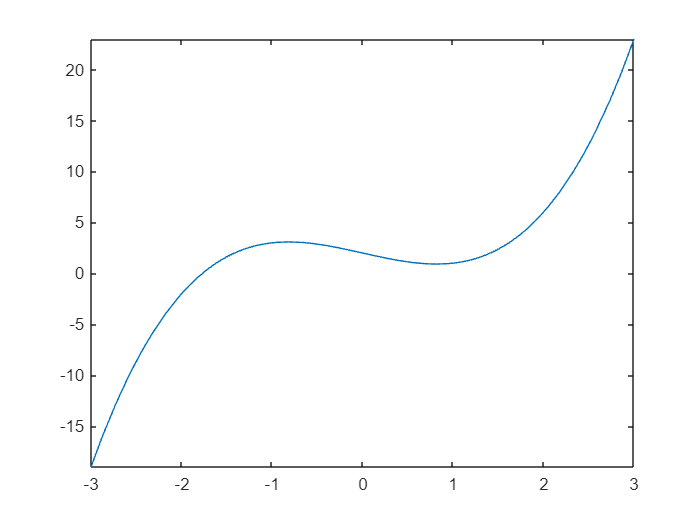

clear
format short

f=@(x) x^3-2*x+2;
fplot(f,[-3,3])

x0=1.0;
%x0=0.85;
%x0=0.979;
%x0=1.1;
z=newton(f,x0,100);
%z=newton2(f,x0,1e-3);
tabla=table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),...
    'VariableNames',{'k','xk','f(xk)','df(xk)','error'});
disp(tabla([1:10 end-10:end],:))

     k     xk    f(xk)    df(xk)    error
    ___    __    _____    ______    _____

      0    1       1         1       NaN 
      1    0       2        -2       Inf 
      2    1       1         1         1 
      3    0       2        -2       Inf 
      4    1       1         1         1 
      5    0       2        -2       Inf 
      6    1       1         1         1 
      7    0       2        -2       Inf 
      8    1       1         1         1 
      9    0       2        -2       Inf 
     90    1       1         1         1 
     91    0       2        -2       Inf 
     92    1       1         1         1 
     93    0       2        -2       Inf 
     94    1       1         1         1 
     95    0       2        -2       Inf 
     96    1       1         1         1 
     97    0       2        -2 

**Ejercicio**: Realizar un análisis gráfico de la convergencia del método de Newton estudiando un problema de punto fijo asociado. 

## Método del punto fijo

### Introducción al algoritmo


$$x=\sqrt{2x+3}$$


clear
format short

g=@(x) sqrt(2*x+3);
g(1)

ans = 2.2361

syms x
g(x)

$$ans = \sqrt{2\,x+3}$$

solve(x==g(x))

$$ans = 3$$

### Convergencia del método

1. Continuidad: $g$ continua en $[0,4]$

- se verifica a mano o graficando la función

2. Condicion de existencia: $g([0,4]) \subset [0,4]$

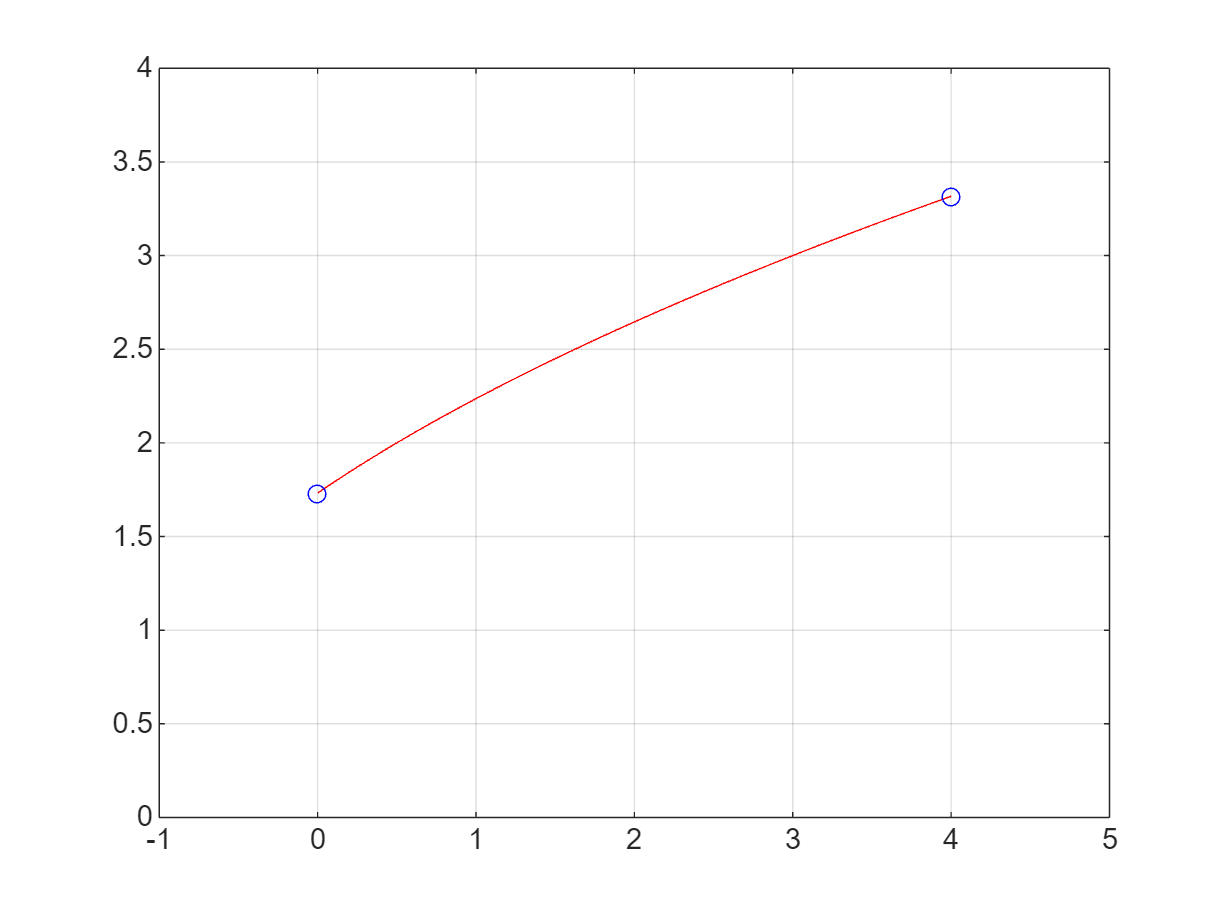

clf
xx = [0:0.01:4]; yy = g(xx);
figure(1)
plot(xx,yy,'r',[0 4],[g(0) g(4)],'ob')
xlim([-1 5]); ylim([0 4])
grid on

- Se visualiza que g([0;4]) cae en [0;4] 

3. condicion de convergencia: $|g'(x)|<1$ para $x \in [0, 4]$

syms x
dg_sym=diff(g(x))

$$dg\_sym = \frac{1}{\sqrt{2\,x+3}}$$

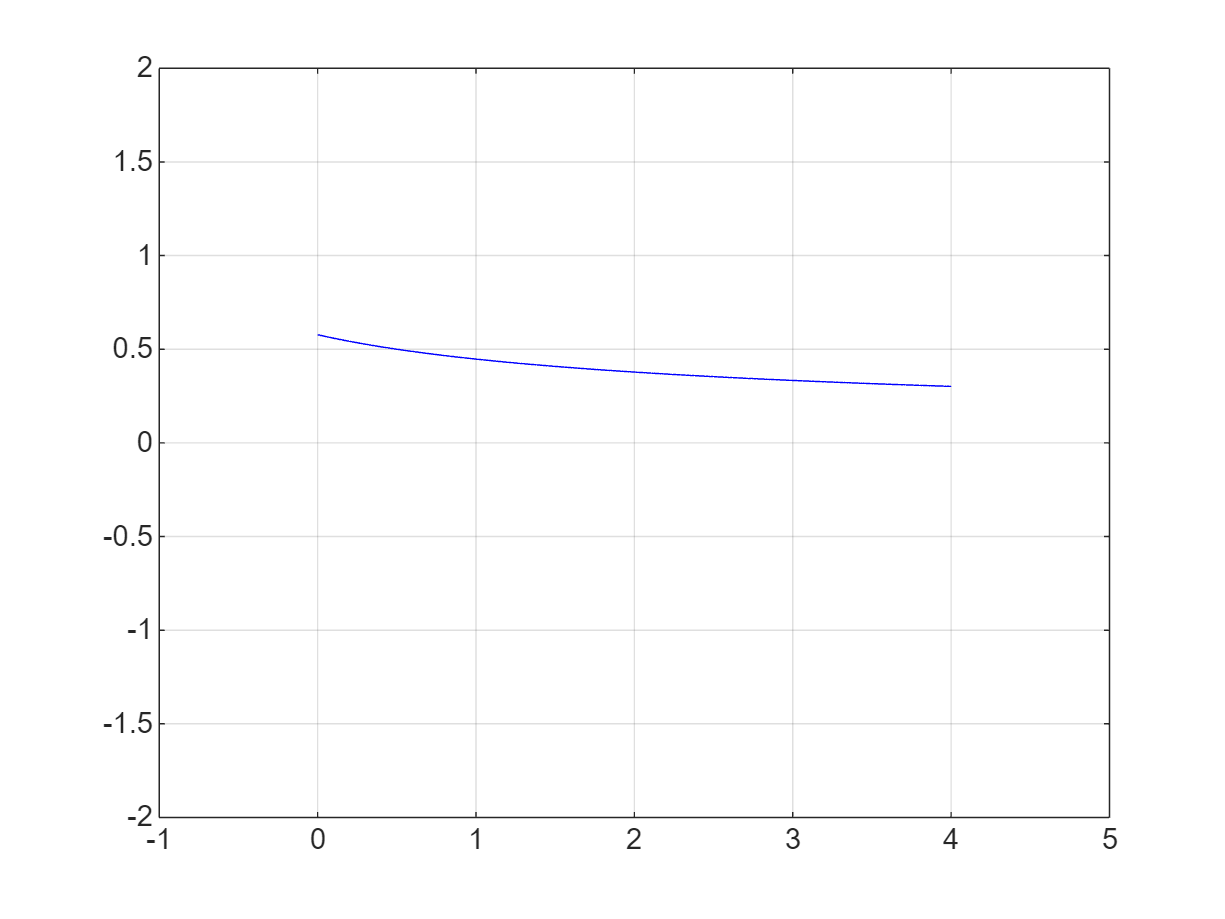

dg=matlabFunction(dg_sym);

xx1=[0:0.01:4]; yy1=abs(dg(xx1));
figure(2)
plot(xx1,yy1,'b')
xlim([-1 5]); ylim([-2 2])
grid on

- Se visualiza que $|g'(x)|<1$ en $[0;4]$

### Implementación del algoritmo

clear 
format long

g=@(x) sqrt(2*x+3);
x0=4;
Maxiter=10;
z=pfijo(g,x0,Maxiter);
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),...
    'VariableNames',{'k','xk','g(xk)','error'}))

    k            xk                g(xk)                 error        
    __    ________________    ________________    ____________________

     0                   4     3.3166247903554                       1
     1     3.3166247903554    3.10374766704879       0.206045378311055
     2    3.10374766704879    3.03438549530174      0.0685871230985172
     3    3.03438549530174     3.0114400194265      0.0228587211000206
     4     3.0114400194265    3.00381091929119     0.00761943645804658
     5    3.00381091929119    3.00127003759781     0.00253980704521425
     6    3.00127003759781    3.00042331599987    0.000846602158935426
     7    3.00042331599987    3.00014110201499    0.000282200712623934
     8    3.00014110201499     3.0000470336363    9.40669039478595e-05
     9     3.0000470336363     3.0000156778378    3.13556346397447e-05
    10     

**Ejericicio**: Realizar la implementación de la función `z=pfijo2(g,x0,Tol)` donde el criterio de parada sea un nivel de tolerancia dada por el argumento `Tol`.

Funciones de usuario:

function z=biseccion(f,a,b,Maxiter)
% aproximación inicial
c=(a+b)/2;
error=NaN; %error=(b-a)/2;
z=[0 a c b f(a) f(c) f(b) error];

% Iteraciones
for k=1:Maxiter
    % seleccionar el subintervalo de búsqueda
    if f(a)*f(c)<0
        b=c; % intervalo izquierdo
    else
        a=c; % intervalo derecho
    end
    % aproximación y nueva fila para z
    c=(a+b)/2;
    error=(b-a)/2;
    z=[z; k a c b f(a) f(c) f(b) error];
end
end

function z=biseccion2(f,a,b,Tol)
% aproximación inicial
k=0;
c=(a+b)/2;
error=(b-a)/2;
z=[k a c b f(a) f(c) f(b) error];

% Condición de parada
N=ceil(log((b-a)/(2*Tol))/log(2)); % max entero + 1
fprintf('Se necesita %d iteraciones\n',N)

% Iteraciones
while error > Tol
    if f(a)*f(c)<0
        b=c; % intervalo izquierdo
    else
        a=c; % intervalo derecho
    end
    % aproximación y nueva fila para z
    k=k+1;
    c=(a+b)/2;
    error=(b-a)/2;
    z=[z; k a b c f(a) f(b) f(c) error];
end
end

function z=newton(f,x0,Maxiter)
% Derivada de f
syms t;
df_sym=diff(f(t),t);
df=matlabFunction(df_sym);

% Aproximación inicial
error=NaN;
z=[0 x0 f(x0) df(x0) error];

% Iteraciones
for k=1:Maxiter
    % aproximación y nueva fila para z
    x1=x0-f(x0)/df(x0);
    error=abs(x1-x0)/abs(x1);
    z=[z; k x1 f(x1) df(x1) error];

    % para la nueva iteración
    x0=x1;
end
end

function z=newton2(f,x0,Tol)
    % Derivada de f
    syms x
    df_sym=diff(f(x));
    df=matlabFunction(df_sym);

    % Aproximación inicial
    k=0;
    z=x0; 
    error=1; % se asume Tol < 1
    z=[k x0 f(x0) df(x0) error];

    % Iteraciones
    while error>Tol
        % aproximación actual
        k=k+1;
        x1=x0-f(x0)/df(x0);
        error=abs(x1-x0)/abs(x1);
        z=[z; k x1 f(x1) df(x1) error];

        % para la siguiente iteración
        x0=x1;
    end
end

function z=pfijo(g,x0,Maxiter)

    % Aproximación inicial
    error=NaN;
    z=[0 x0 g(x0) error];
    
    % Iteraciones
    for k=1:Maxiter
        % aproximación actual
        x1=g(x0);
        error=abs(x1-x0)/abs(x1);
        z=[z; k x1 g(x1) error];

        % para la siguiente iteración
        x0=x1;
    end
end